# simulated ecg

f0 = figure('Name','FIGURE');
f1 = figure('Name','60BPM FASTCLIP');
f2 = figure('Name','60BPM AGPOSS');
f3 = figure('Name','100BPM FASTCLIP');
f4 = figure('Name','100BPM AGPOSS');
f5 = figure('Name','100BPM NORMAL SINUS RHYTHM');

2秒分(1000samples)のプロットを比較

x = linspace(0,1000,1000);

align data

y1 = sim060d3(10001:11000);
y2 = sim060f3(10063:11062);
y3 = sim060a3(9854:10853);
y4 = sim100d3(10001:11000);
y5 = sim100f3(9991:10990);
y6 = sim100a3(10061:11060);
%

レベルの違いを吸収するために正規化

y1n = normalize(y1);
y2n = normalize(y2);
y3n = normalize(y3);
y4n = normalize(y4);
y5n = normalize(y5);
y6n = normalize(y6);

plot

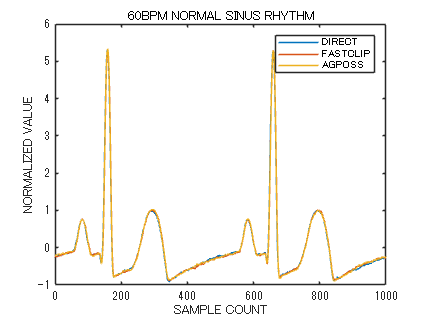

figure(f0);
plot(x, y1n, x, y2n, x, y3n)
legend("DIRECT", "FASTCLIP", "AGPOSS");
xlabel("SAMPLE COUNT");
ylabel("NORMALIZED VALUE");
title("60BPM NORMAL SINUS RHYTHM");

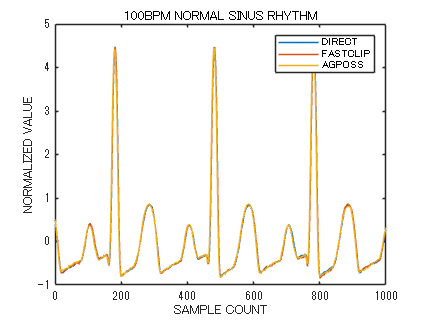

figure(f0);
plot(x, y4n, x, y5n, x, y6n)
legend("DIRECT", "FASTCLIP", "AGPOSS");
xlabel("SAMPLE COUNT");
ylabel("NORMALIZED VALUE");
title("100BPM NORMAL SINUS RHYTHM");

### **correlation coefficients**

60BPM Direct / Fastclip

cc1 = corrcoef(y1,y2);
cc1 = cc1(1,2)

cc1 = 0.9969

60BPM Direct / AGPoss

cc2 = corrcoef(y1,y3);
cc2 = cc2(1,2)

cc2 = 0.9983

100BPM Direct / Fastclip

cc3 = corrcoef(y4,y5);
cc3 = cc3(1,2)

cc3 = 0.9991

100BPM Direct / AGPoss

cc4 = corrcoef(y4,y6);
cc4 = cc4(1,2)

cc4 = 0.9915

#### 60BPM Fastclip/AGPoss

cc5 = corrcoef(y2,y3);
cc5 = cc5(1,2)

cc5 = 0.9992

#### 100BPM Fastclip/AGPoss

cc6 = corrcoef(y5,y6);
cc6 = cc6(1,2)

cc6 = 0.9941

### Plot (raw value)

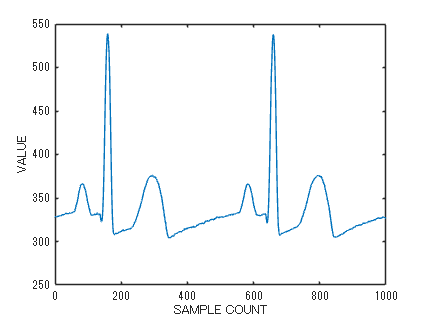

%60f
figure(f1);
plot(x, y2)
ylim([250 550])
xlabel("SAMPLE COUNT");
ylabel("VALUE");

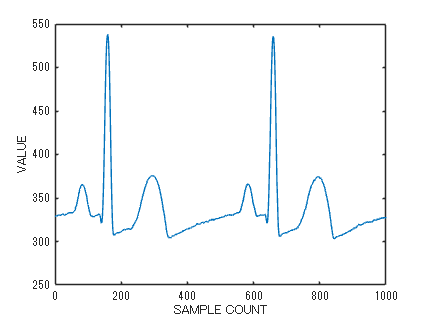

%title("100BPM NORMAL SINUS RHYTHM");
%60a
figure(f2);
plot(x, y3)
ylim([250 550])
xlabel("SAMPLE COUNT");
ylabel("VALUE");

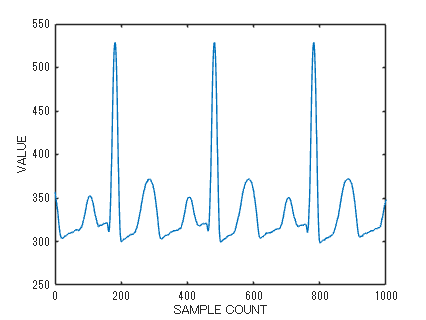

%title("100BPM NORMAL SINUS RHYTHM");
%100f
figure(f3);
plot(x, y5)
ylim([250 550])
xlabel("SAMPLE COUNT");
ylabel("VALUE");

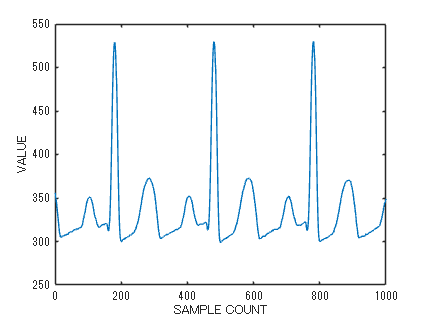

%title("100BPM NORMAL SINUS RHYTHM");
%100a
figure(f4);
plot(x, y6)
ylim([250 550])
xlabel("SAMPLE COUNT");
ylabel("VALUE");

%title("100BPM NORMAL SINUS RHYTHM");
